# RC Circuits

[⇦ DC Circuit Analysis Overview](matlab: OpenOverview)

**Learning Goals**

- Simulate charging and discharging RC circuits.

- Plot solutions of RC circuit differential equations.

- Measure the time constant of an RC circuit.

## Introduction

As the name suggests, a series RC circuit contains a resistor and a capacitor in series. If a voltage source is added to the loop, the source charges the capacitor. This circuit is known as a *charging circuit*. Without the source, it is a *discharging circuit*. Both of these circuits exist in an RC circuit with a switch.

   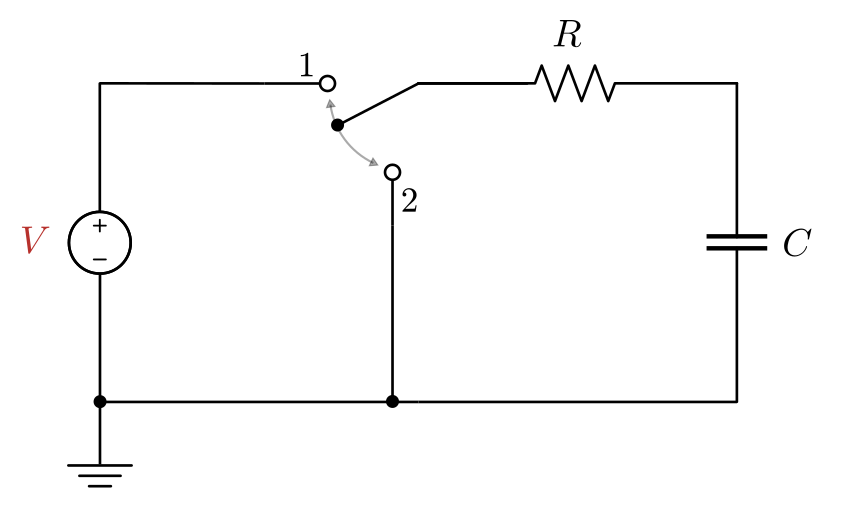

*RC circuit with a switch. With the switch in position (1), the source charges the capacitor. The capacitor discharges through the resistor if the switch is in position (2).*

In this lesson, you will analyze the transient responses of RC circuits.

  **Activity. **The behavior of an RC circuit is simulated in:

[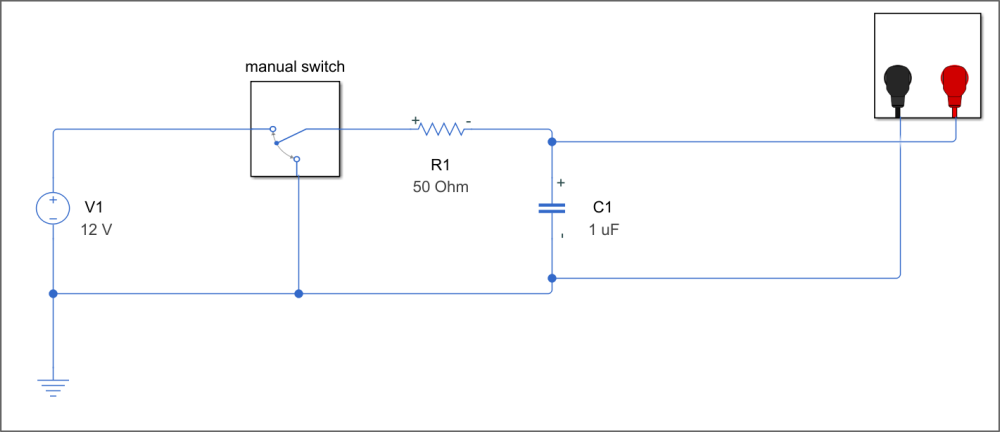](matlab: RCCircuit)

[`RCCircuit.slx`](matlab: RCCircuit)

Open the model and follow the steps listed in the canvas to complete the activity.

## Charging circuit

In this section, the differential equation for the charging RC circuit will be derived and solved. Suppose that the switch has been in position 2 for a long time (so the capacitor has been completely discharged) and then flips to position 1 at time $t = 0$.

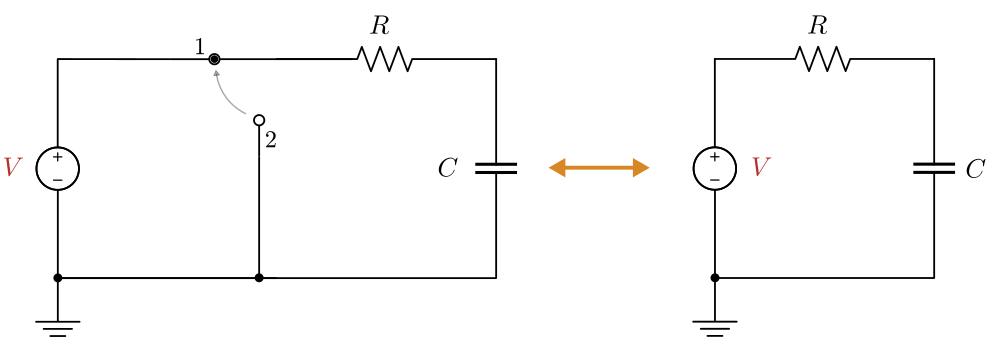

*Charging RC circuit*

You can model the characteristics of the charging circuit by applying KVL (Kirchhoff's voltage law):


$$-V + V_{R} + V_{C} = 0$$


Applying Ohm's law yields


$$-V + i R + V_C = 0$$


The voltage across the capacitor increases as charge builds up on the capacitor. This implies that the voltage across the capacitor increases in proportion to the current flowing through the resistor, $i$:


$$\frac{\text{d}V_C}{\text{d}t} = \frac{1}{C}i$$


Therefore

        
$$RC \frac{\text{d}V_c}{\text{d}t} + V_c = V$$


where $R$ is the resistance, $C$ is the capacitance, and $V_C(t)
$ is the time-dependent voltage across the capacitor. Solving the differential equation and using the initial condition$V_C(0)  = 0$ yields the solution for the charging circuit:


$$V_C(t) = V \cdot \left( 1-  \text{e}^{-\frac{t}{RC}}  \right)$$


  **Activity.  **Adjust the sliders for the resistor and capacitor to plot the charging function. For each parameter ($R$, $C$, and $V$), answer the following questions:

- Set the parameter to the minimum value and then gradually increase it. Does the charging time increase, decrease, or neither? Why does this make sense?

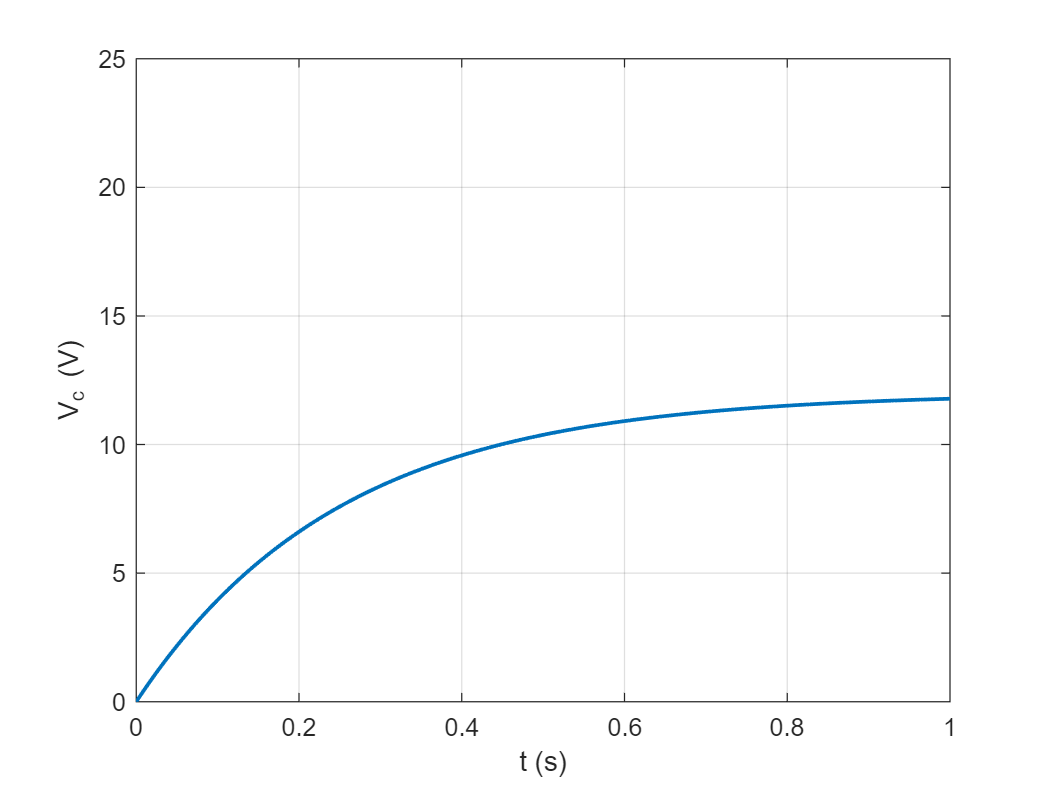

% Set the parameters
R = 5000; % Ohms
C = 0.00005; % Farads
V = 12; % Volts
% This code plots the result
t = linspace(0,1,250);
Vc = V*(1-exp(-t/(R*C)));
plot(t,Vc,"LineWidth",1.5)
xlabel("t (s)")
ylabel("V_c (V)")
axis([0 1 0 25])
grid on

## Discharging circuit

With the charging circuit solution derived, it is relatively easy to find the discharging circuit solution. For the discharging circuit, suppose that the switch has position 1 for a long time (so the capacitor has been fully charged) and then flips to position 2. 

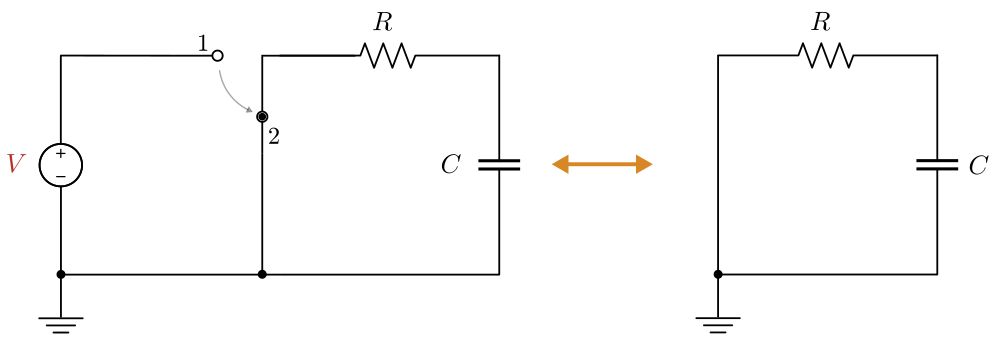

*Discharging RC circuit*

Applying the KVL yields the same equation as the charging circuit, but without the voltage source:


$$V_{R} + V_{C} = 0$$


In this case, the voltage differential equation is

    
$$RC \frac{\text{d}V_c}{\text{d}t} + V_c = 0$$


Solving the differential equation and using the assumption that the capacitor is charged (i.e., $V_C(0) = V$) yields the solution:


$$V_C(t) = -V \text{e}^{-\frac{t}{RC}}$$


  **Activity.  **Adjust the sliders for the resistor and capacitor to plot the charging function. For each parameter ($R$, $C$, and $V$), answer the following question:

- Set the parameter to the minimum value and then gradually increase it. Does the discharging time increase, decrease, or neither? Why does this make sense?

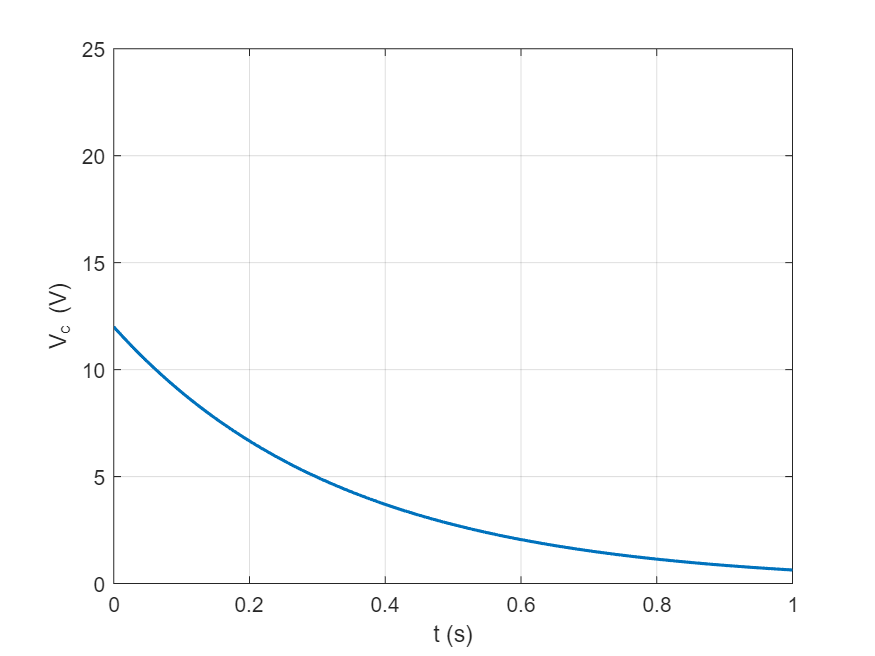

% Set the parameters
R = 5000; % Ohms
C = 0.000068; % Farads
V = 12; % Volts
% This code plots the result
t = linspace(0,1,250);
Vc = V*exp(-t/(R*C));
plot(t,Vc,"LineWidth",1.5)
xlabel("t (s)")
ylabel("V_c (V)")
axis([0 1 0 25])
grid on

## Time constant

You probably noticed that there was an exponential term in the solution of both the charging and discharging circuits. The rate that the capacitor charges or discharges is determined by the constant inside the exponential. This is known as the *time constant *of the circuit, $\tau = RC$. Plug $\tau$ into the expression for the charging circuit, and find


$$V_C(\tau) = V \cdot ( 1-  \text{e}^{-\frac{RC}{RC}} ) = V \cdot (1- \text{e}^{-1}) \approx 0.632 \  \text{V}$$


This implies that $\tau$ is the amount of time it takes for the capacitor to charge to 63.2% of its maximum value ($V$, the source value). The time constant is commonly used to characterize the behavior of the RC circuit. Notice that $\tau$ is also the time required to discharge 63.2% of the capacitor's current voltage in the discharging circuit.

  **Activity. **

**Task 1. **For the RC circuit simulated in the Simscape model example, $R = 50$ $\Omega$ and $C = 1$ µF. What is the time constant of the circuit, $\tau$? Open the circuit and simulate the model. Does the value of $\tau$ match the amount of time taken to charge or discharge 63% of the capacitor?

[](matlab: RCCircuit)

[`RCCircuit.slx`](matlab: RCCircuit)

**Task 2.** Keeping the capacitor value $C = 1$ µF, what resistor would be required to produce a time constant of 5 ms? Validate your answer by using that value in the Simscape model and simulating the circuit. Does the circuit require 5 ms to reach 63% of the maximum voltage?

### Measuring the time constant

You can estimate the time constant by measuring the time it takes for the circuit to charge to 63% of its maximum voltage. For example, consider the plot of a charging capacitor shown below.

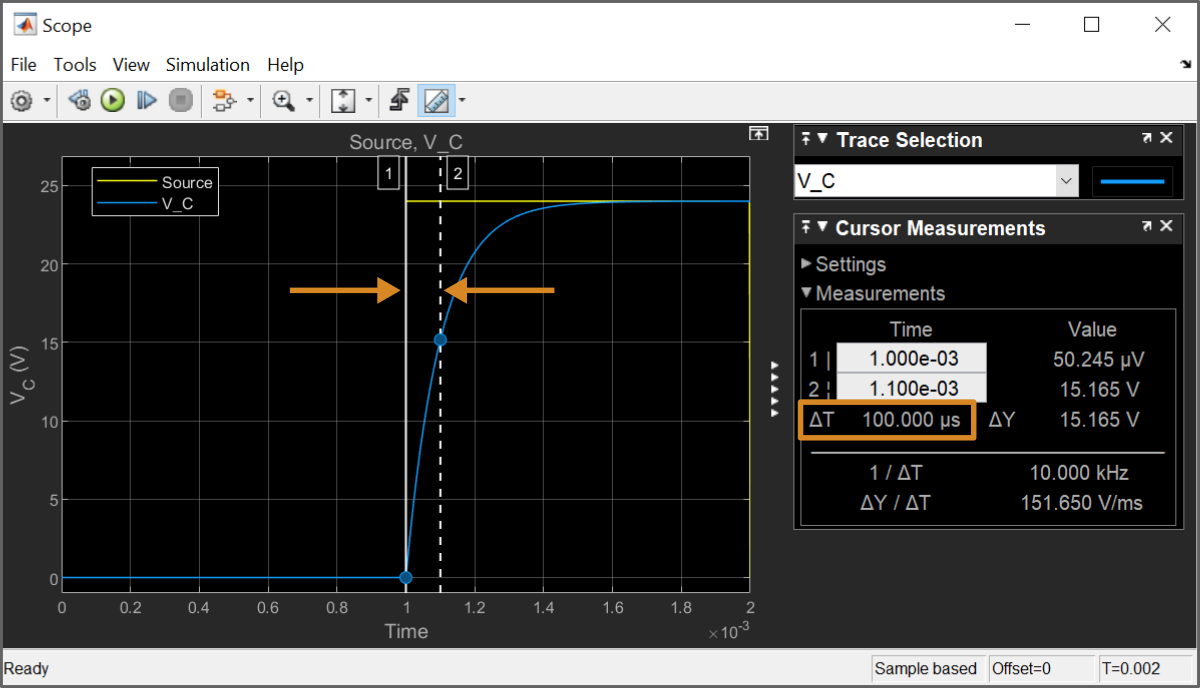

*Example of measuring the time constant, *$\tau$

In this example, the time constant has been measured using the **Cursor Measurements** tool in a Simulink scope. The details of the process are listed below.

- The capacitor is charged from 0 to 24 V, so the time constant is the time required to reach $24 \cdot 0.632 $ V $= 15.2$ V. 

- The first cursor is placed at t = 1 ms, when the source switches from 0 to 24 V. 

- The second cursor is placed when the voltage reaches 15.2 V. 

- The time constant is the measured time difference, $\tau = 0.1$ ms.

  **Activity. **The Simscape model linked below contains an RC circuit that is switched by a variable voltage source. Complete the activity by opening the model and following the instructions inside to measure the time constant.

[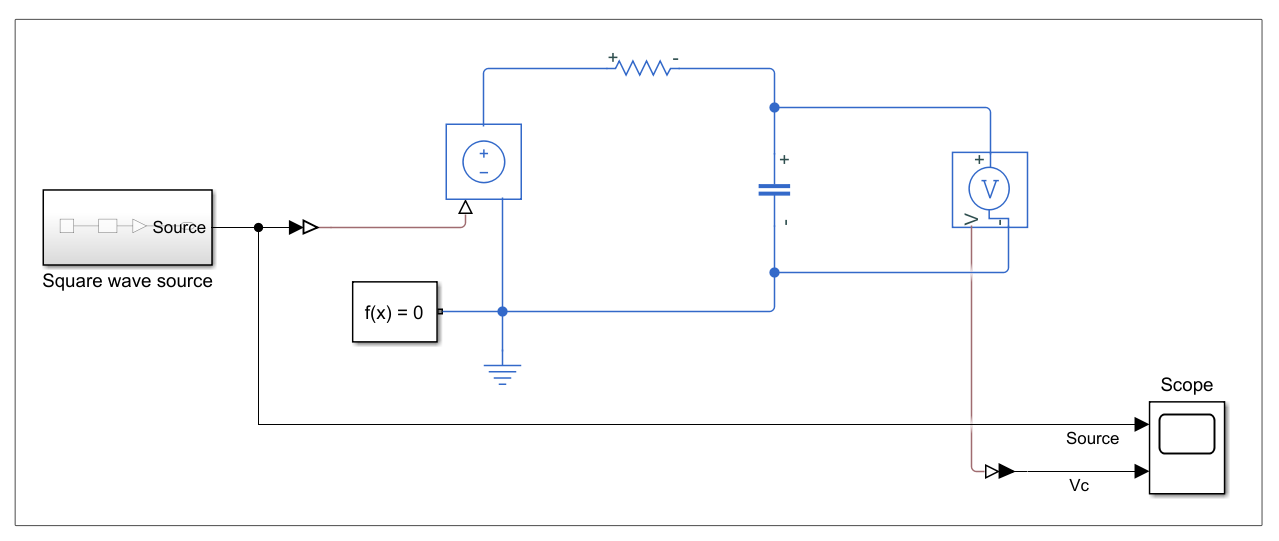](matlab: RCCircuitTau)

[`RCCircuitTau.slx`](matlab: RCCircuitTau)

[⇦ DC Circuit Analysis Overview](matlab: OpenOverview)